# Activity 7: Feature Extraction from Labeled Blobs

## Morphological Operations and RegionProps

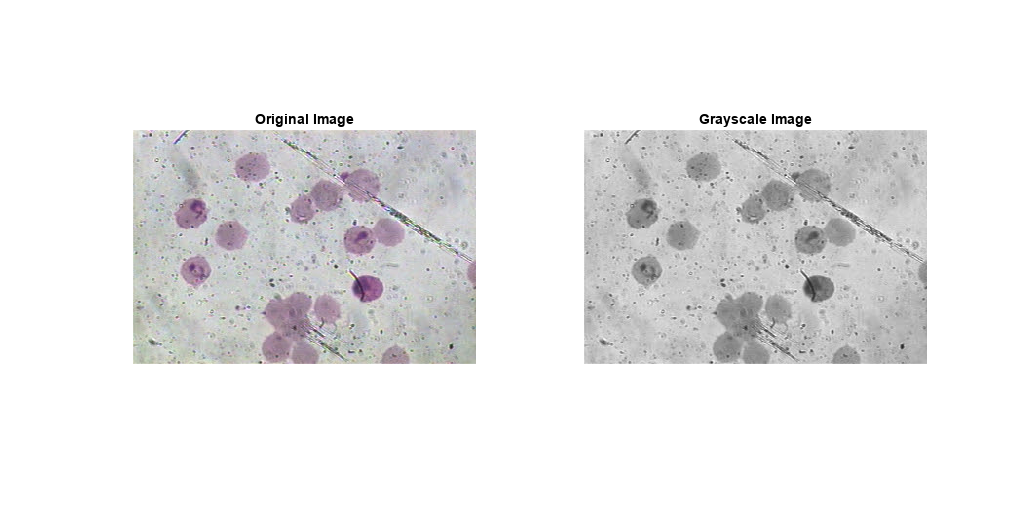

I = imread("malaria(1).jpeg");
Igray = rgb2gray(I);
figure('Position', [200, 200, 1024, 512]);
subplot(1,2,1); imshow(I); title("Original Image");
subplot(1,2,2); imshow(Igray); title('Grayscale Image');

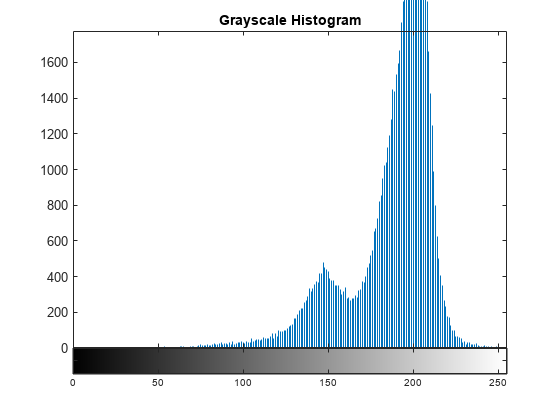

figure; imhist (Igray); title("Grayscale Histogram");

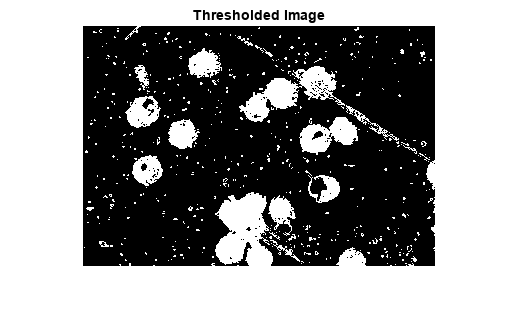

BW = and(Igray < 164, Igray > 100);
figure; imshow(BW); title('Thresholded Image');

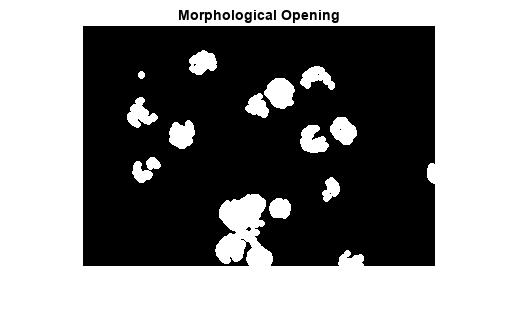

SE = strel("disk",4); 
BW2 = imopen(BW,SE);
figure('Position', [200, 200, 1024, 512]);
imshow(BW2); title('Morphological Opening');

%% Demo on Regionprops
BWL = bwlabel(BW2);
figure; imagesc(BWL); colorbar;
features = regionprops(BWL,"Area","Eccentricity","Perimeter","Centroid","BoundingBox")

features = 15×1 struct array with fields:
    Area
    Centroid
    BoundingBox
    Eccentricity
    Perimeter


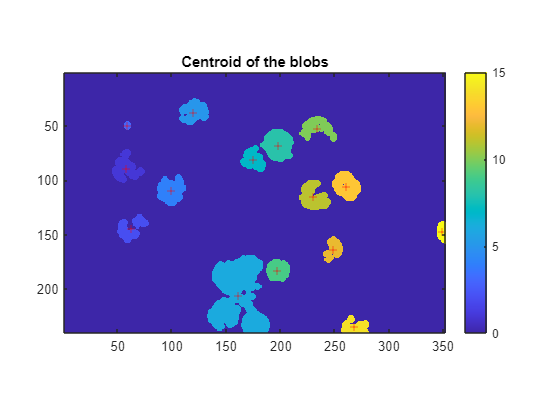


% Put label number on Centroid of Blobs
Centroid = cat(1,features.Centroid);
hold on;
plot(Centroid(:,1),Centroid(:,2),'r+'); axis image; 
title('Centroid of the blobs');

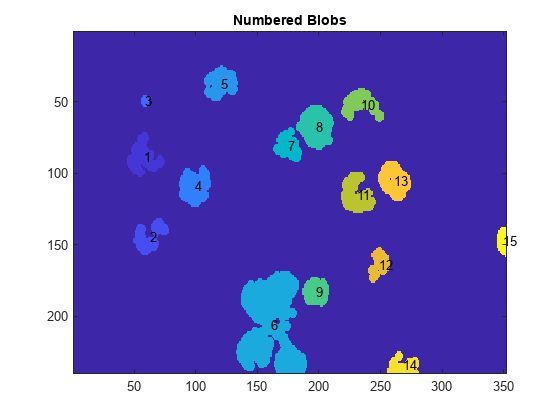

%% Put label numbers on Centroid of blobs
figure; imagesc(BWL); title('Numbered Blobs'); hold on;
for i = 1:size(Centroid,1)
 text(Centroid(i,1), Centroid(i,2), num2str(i));
end

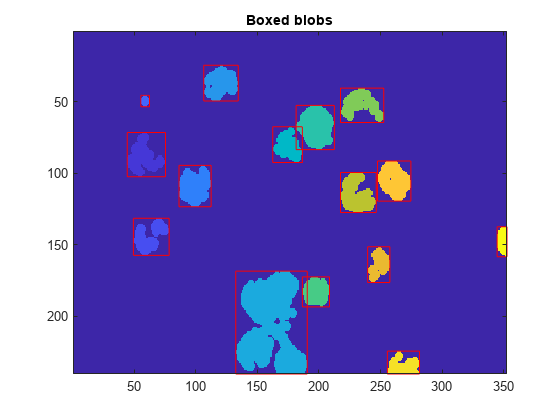

%% Put bounding boxes around each blob
figure; imagesc(BWL); title('Boxed blobs'); hold on;
bb = cat(1,features.BoundingBox);
for i = 1:size(features,1)
 rectangle('Position',bb(i,:),'EdgeColor','r');
end